# PV Orientation

clear all;
close all;

## Grundgerüst

%Umwandlung von dem Abgabedatum
datum = datetime('2024-10-17');
doy = day(datum, "dayofyear");
% Berechne delta in Grad
delta = 23.45 * sind((360/365) * (doy + 284));
% Zeit
t_h= 1:0.1:24;
t_j = 1:1:365;
% Standortbreite in Grad für Sölden
phi = 46.97;

% Berechne den Winkel alpha für verschiedene Stunden t
%Methode1
alpha = @(t) asind((sind(phi) * sind(delta)) + (cosd(phi) * cosd(delta) * cosd(15*(t - 12))));
alpha_values_h = alpha(t_h)

alpha_values_h =   -51.5635  -51.1264  -50.6536  -50.1464  -49.6062  -49.0344  -48.4325  -47.8018  -47.1436  -46.4595  -45.7507  -45.0185  -44.2642  -43.4890  -42.6941  -41.8807  -41.0497  -40.2023  -39.3395  -38.4622  -37.5714  -36.6679  -35.7525  -34.8261  -33.8894  -32.9431  -31.9879  -31.0245  -30.0536  -29.0756  -28.0912  -27.1011  -26.1055  -25.1052  -24.1006  -23.0922  -22.0804  -21.0657  -20.0485  -19.0293  -18.0084  -16.9863  -15.9633  -14.9398  -13.9163  -12.8930  -11.8704  -10.8488   -9.8286   -8.8102


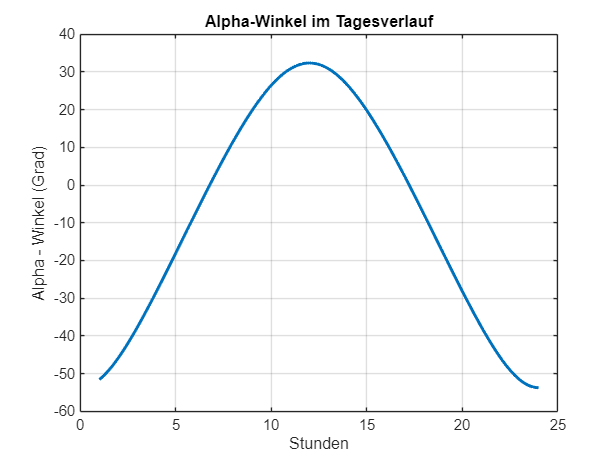

figure;
plot(t_h, alpha_values_h, 'LineWidth', 2);
xlabel('Stunden');
ylabel('Alpha - Winkel (Grad)');
title('Alpha-Winkel im Tagesverlauf');
grid on;

% %Methode2
% for t = 1:24
%      alpha(t) = asind((sind(phi) * sind(delta)) + (cosd(phi) * cosd(delta) * cosd(15*(t - 12))));
% end


%Sonnenuntergang
time_down = (acosd(-tand(phi)*tand(delta)) / 15) + 12

time_down = 17.2221

datestr( time_down/24, "HH:MM:SS")

ans = '17:13:19'

%Sonnenaufgang
time_up = -(acosd(-tand(phi)*tand(delta)) / 15) + 12

time_up = 6.7779

datestr( time_up/24, "HH:MM:SS")

ans = '06:46:40'

%Azimut
azimut_winkel = @(t,alpha)  real(acosd((sind(delta)-sind(alpha(t)).*sind(phi)) ./ (cosd(alpha(t)).*cosd(phi))));
azimut_wikel_value_h = azimut_winkel(t_h,alpha)

azimut_wikel_value_h =    24.1494   26.4031   28.6164   30.7876   32.9158   35.0001   37.0401   39.0357   40.9870   42.8943   44.7584   46.5798   48.3597   50.0989   51.7987   53.4603   55.0850   56.6741   58.2290   59.7510   61.2416   62.7022   64.1341   65.5386   66.9172   68.2712   69.6018   70.9102   72.1978   73.4657   74.7151   75.9471   77.1629   78.3634   79.5497   80.7228   81.8837   83.0333   84.1726   85.3025   86.4237   87.5372   88.6439   89.7444   90.8395   91.9302   93.0170   94.1008   95.1822   96.2619


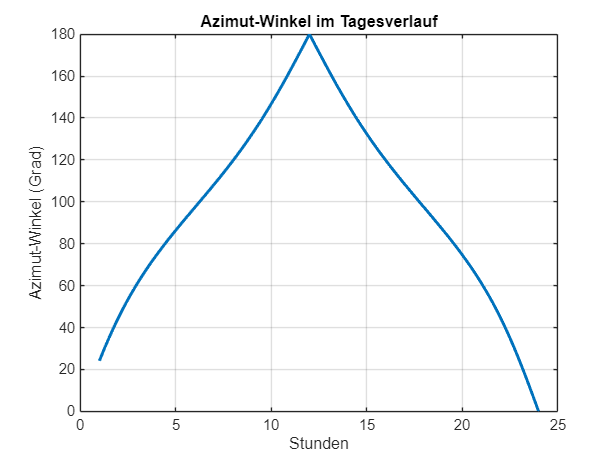

figure;
plot(t_h, azimut_wikel_value_h, 'LineWidth', 2);
xlabel('Stunden');
ylabel('Azimut-Winkel (Grad)');
title('Azimut-Winkel im Tagesverlauf');
grid on;